clear
load Data\data4.mat
n=length(data.CzasLokalnyUTC0100)

n = 3601

data.CzasLokalnyUTC0100(1:4)

ans = 4×1 datetime array
   17/06/2024 11:30:00
   17/06/2024 11:31:00
   17/06/2024 11:32:00
   17/06/2024 11:33:00


data.CzasLokalnyUTC0100(n-3:n)

ans = 4×1 datetime array
   19/06/2024 23:27:00
   19/06/2024 23:28:00
   19/06/2024 23:29:00
   19/06/2024 23:30:00


T=60; %[s]
fs=1/T; %[Hz]
t=T*(0:n-1);

Kompresor=data.StanKompresor;
StanCzujnikaZamkniecia=data.StanCzujnikZamkniciaDrzwi;

TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
TemperatureSterujaca=0.1*data.TemperaturaSterujca;

X=[Kompresor,StanCzujnikaZamkniecia,...
    TemperaturaOtoczenia,TemperatureSterujaca]';

[dataWithoutNans,nan_indices]  = GetRidOfNans(X);
find(nan_indices,~0)


ans =

  0×1 empty double column vector



no nans

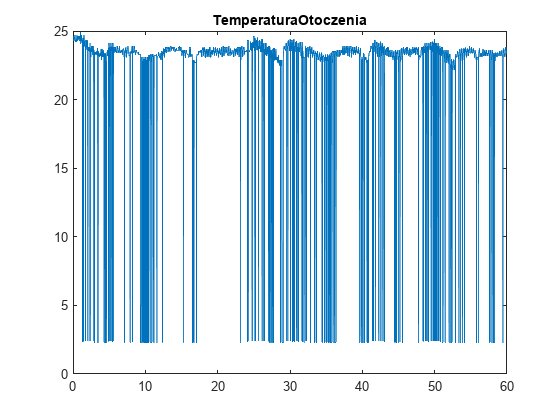

plot(t/(60*60),X(3,:))
title('TemperaturaOtoczenia')

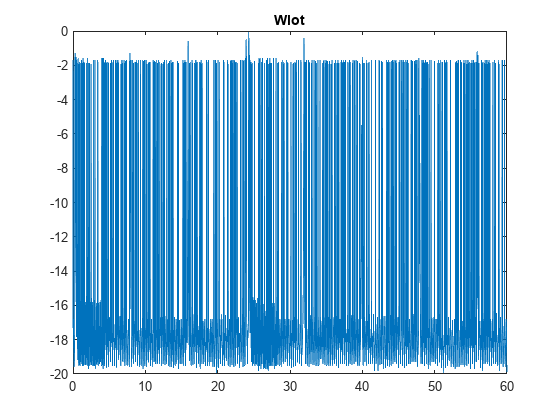

plot(t/(60*60),X(4,:))
title('Wlot')

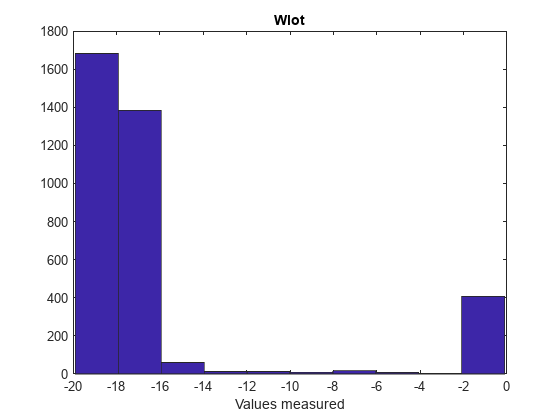

hist(X(4,:))
title('Wlot')
xlabel('Values measured')

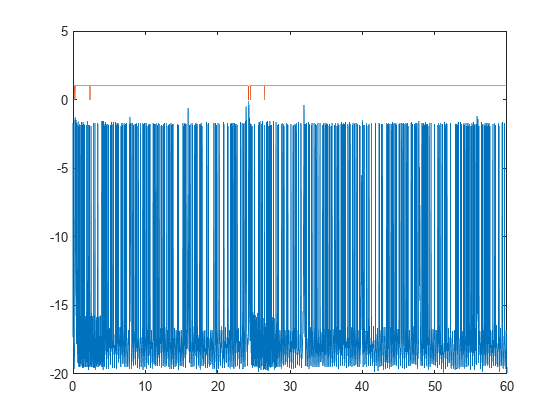

plot(t/(60*60),X(4,:))
hold on
plot(t/(60*60),X(2,:));hold off

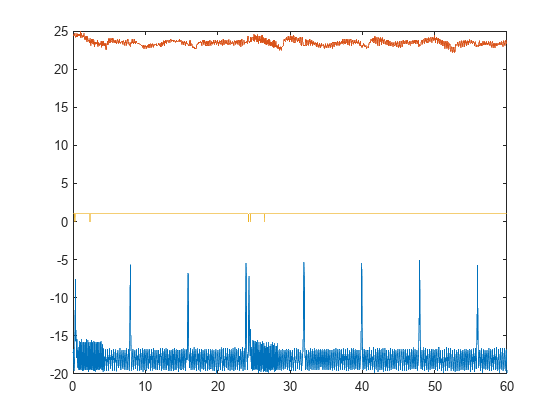

X_toFilter=X(3:4,:);
threshold=[0,5;-5,5];
for i = 1:2
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end

plot(t/(60*60),X_filtered(2,:))
hold on
plot(t/(60*60),X_filtered(1,:))
plot(t/(60*60),X(2,:));hold off